# Repaso de MATLAB

#### Simulacro 3

*Overview by @alujan*

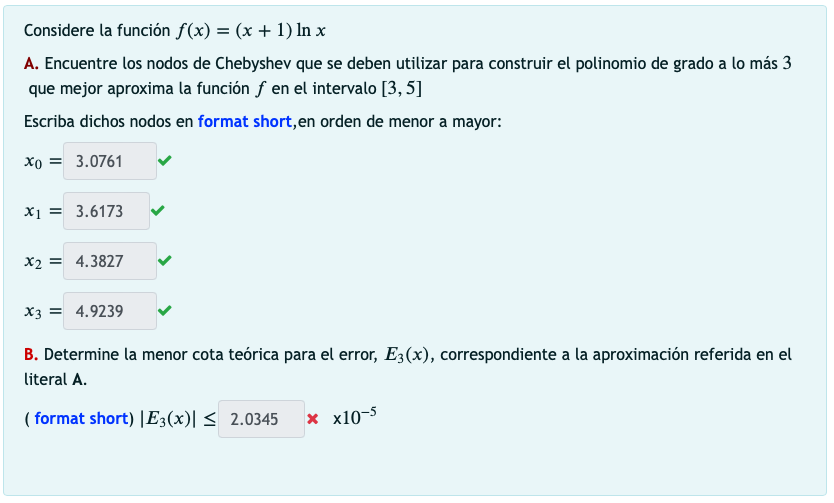

clear

syms f(x)

help nodoschebyshev

  Entrada   - fun funcion creada con @
            - n es el grado del polinomio interpolante de Lagrange-Chebyshev
            - a es el extremo izquierdo
            - b es el extremo derecho
  Salida   
            - X contiene las abscisas
            - Y contiene las ordenadas



f(x) = (x + 1) .* log(x);

[X, Y] = nodoschebyshev(f, 3, 3, 5);

d4f(x) = diff(f, x, 4)

$$d4f(x) = \frac{8}{x^{3}}-\frac{6\,\left(x+1\right)}{x^{4}}$$

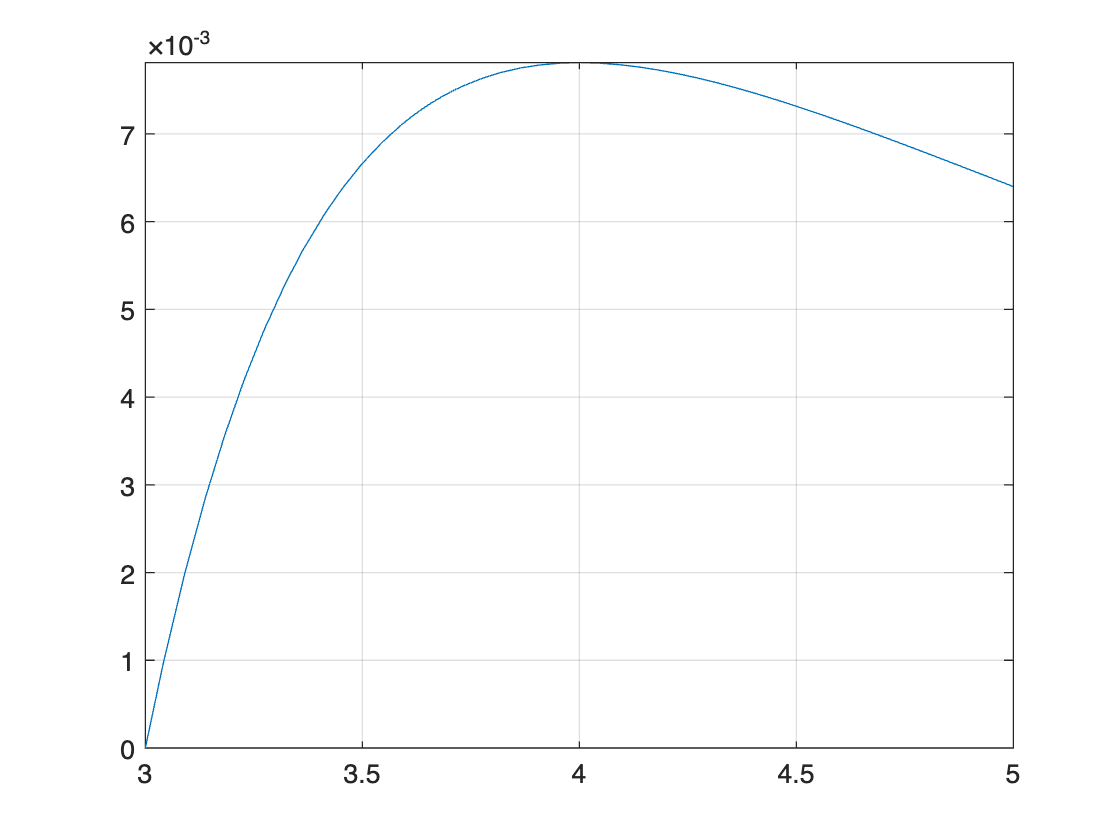

clf('reset')
fplot(d4f, [3, 5])
grid on

d5f(x) = diff(d4f, x);

d5f = matlabFunction(d5f);

c = bisect(d5f, 3, 5, 1E-15);

% Durante el simulacro al concluir este error tuve una falla en la
% definición, consideré un 1/2 adicional que obtiene la mitad de la
% respuesta.
Err = eval(1/2^3 * (5 - 3)^4 / 2^4 * abs(d4f(c)) / 24)

Err = 4.0690e-05

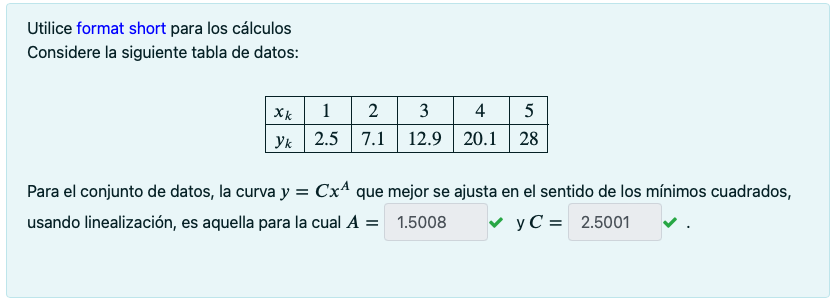

clear

X = 1:5;
Y = [2.5 7.1 12.9 20.1 28];

logX = log(X);
logY = log(Y);

help lsline

  Entrada  - X es el vector de abscisas   1 x n
           - Y es el vector de ordenadas  1 x n
  Salida   - A es el coeficiente de  x  en  Ax + B
           - B es el coeficiente constante en  Ax + B



[A, logB] = lsline(logX, logY)

A = 1.5008

logB = 0.9163

A, B = exp(logB)

A = 1.5008

B = 2.5001

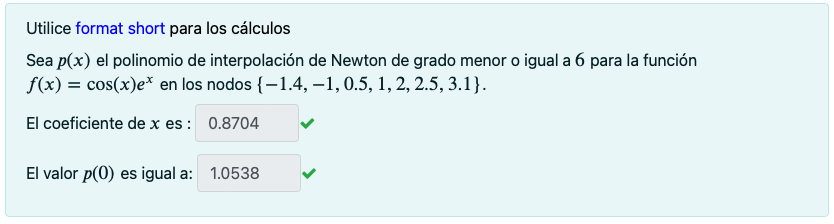

clear

f = @(x) cos(x).*exp(x);

X = [-1.4, -1, 0.5, 1, 2, 2.5, 3.1]

X =    -1.4000   -1.0000    0.5000    1.0000    2.0000    2.5000    3.1000


Y = f(X)

Y =     0.0419    0.1988    1.4469    1.4687   -3.0749   -9.7599  -22.1788


help newpoly

  Entrada   - X es un vector que contiene la lista de abscisas
            - Y es un vector que contiene la lista de ordenadas
  Saldia    - C es un vector que contiene los coeficientes del
              polinomio interpolante de Newton
            - D es la tabla de diferencias divididas



Coef = newpoly(X, Y)

Coef =     0.0279   -0.0916   -0.2151   -0.1438   -0.0328    0.8704    1.0538


polyval(Coef, 0)

ans = 1.0538

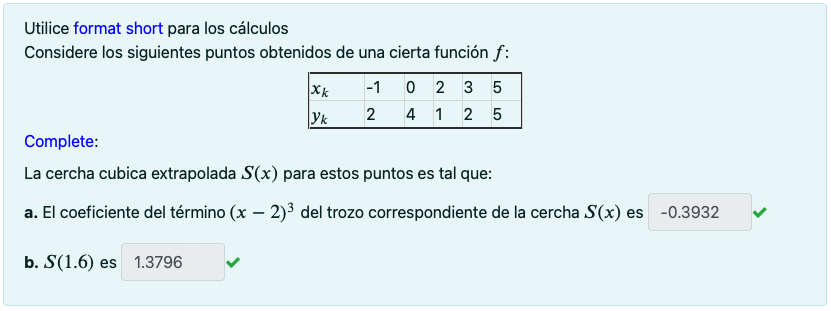

clear

X = [-1 0 2 3 5];
Y = [2 4 1 2 5];

help csextrapolado

  S'' extrapola en los extremos
 
  Entrada   - X es el vector de abscisas  1 x n
            - Y es el vector de ordenadas 1 x n
  Salida    - S: las filas de S son los coeficientes 
                 para los interpolantes (trazadores) cubicos



S = csextrapolado(X, Y)

S =     0.5812   -3.4915    4.9103    2.0000
    0.5812   -1.7479   -0.3291    4.0000
   -0.3932    1.7393   -0.3462    1.0000
   -0.3932    0.5598    1.9530    2.0000


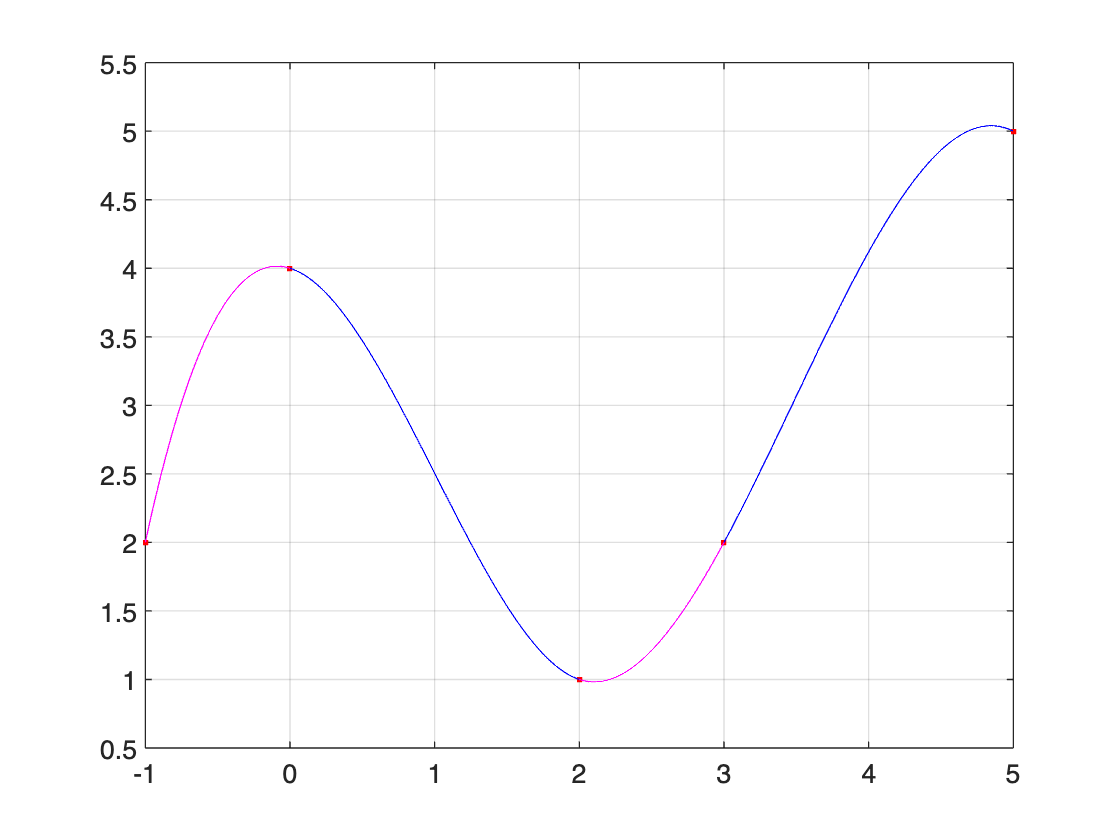

GraficaCercha(X, Y, S)
grid on

polyval(S(2, :), (1.6 - X(2)))

ans = 1.3796

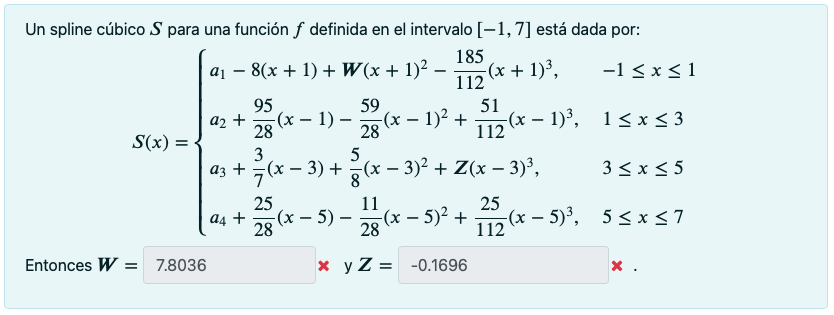

% El punto aparece con falla del simulacro por un error en los formatos a
% emplear. Se puede validar que el analisis hecho no tiene problemas, solo
% que el formato evaluado no corresponde al dado.
format long

clear

syms W Z

Eq1 = 2*W - 3*2*185 / 112*(2) == 2 * -59 / 28

$$Eq1 = 2\,W-\frac{555}{28}=-\frac{59}{14}$$

W = eval(solve(Eq1))

W =    7.803571428571429


Eq2 = 2 * 5/8 + 3*2 * Z * (2) == 2 * -11/28

$$Eq2 = 12\,Z+\frac{5}{4}=-\frac{11}{14}$$

Z = eval(solve(Eq2))

Z =   -0.169642857142857
